# **Predict Utility Bill Probability **

Channel ID: **1679858**

Author: [mwa0000025992853](https://thingspeak.com/users/mwa0000025992853)

Read API Key: `GZI98SNTG9C41EN7`

clc;
close;
warning('off','all')

## Reading Data From Thingspeak

% readChannelID =  1679858;
% data = thingSpeakRead(readChannelID,'NumDays',15,'Fields',[1 2 3 4 5 6 7]);
% Electricity_Unit= thingSpeakRead(readChannelID,'Fields',1);
% Electricity_Taka= thingSpeakRead(readChannelID,'Fields',2);
% Gas_Taka        = thingSpeakRead(readChannelID,'Fields',3);
% Gas_Unit        = thingSpeakRead(readChannelID,'Fields',4);
% Water_Unit      = thingSpeakRead(readChannelID,'Fields',5);
% Water_Taka      = thingSpeakRead(readChannelID,'Fields',6);
% Consumtion_Taka = thingSpeakRead(readChannelID,'Fields',7);

## **Total Consumtion Taka Prediction**

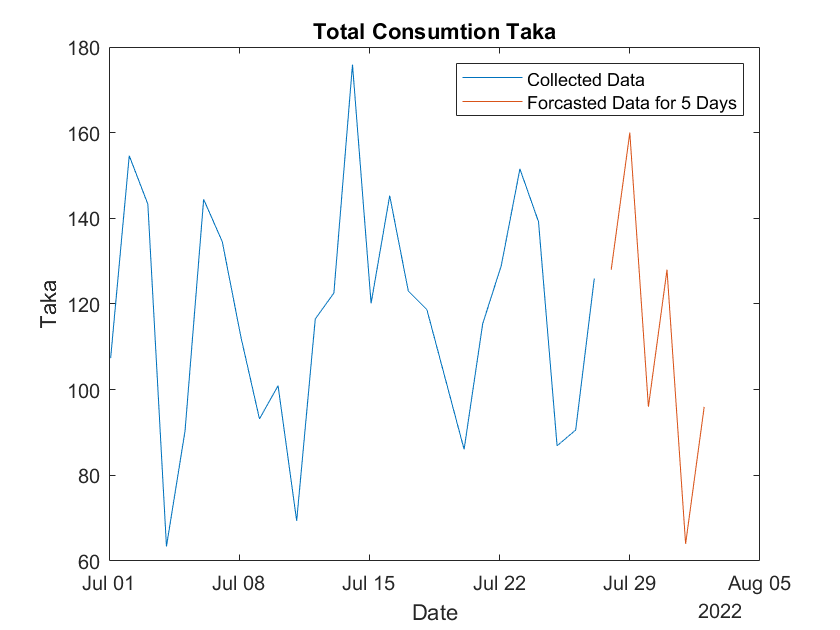

%for i=1:20

    x=datenum(time);
    t=Consumtion_Taka';
    X=x';
   % i
    p = polyfit(X, t, 14);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Consumtion Taka')
    ylabel('Taka')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end

## Total Electricity Taka Prediction

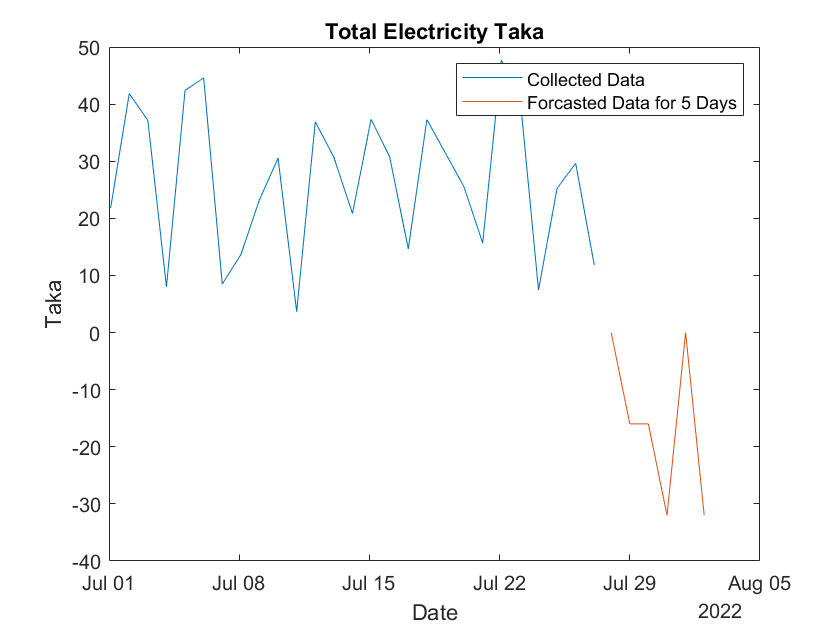

%for i=1:20

    x=datenum(time);
    t=Electricity_Taka';
    X=x';
    %i
    p = polyfit(X, t, 14);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Electricity Taka')
    ylabel('Taka')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end

## Total Electricity Unit Prediction

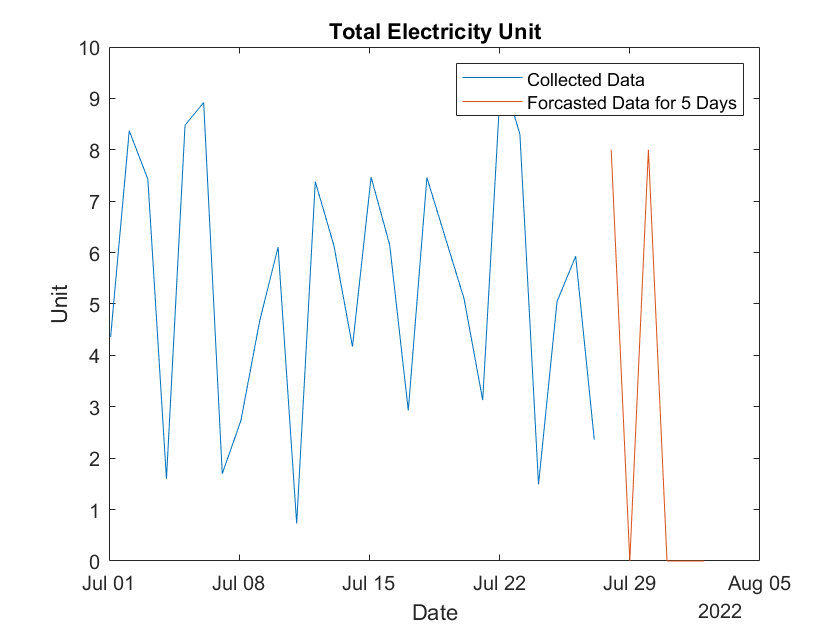

%for i=1:20

    x=datenum(time);
    t=Electricity_Unit';
    X=x';
   % i
    p = polyfit(X, t, 19);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Electricity Unit')
    ylabel('Unit')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end


## Total Gas Unit Prediction

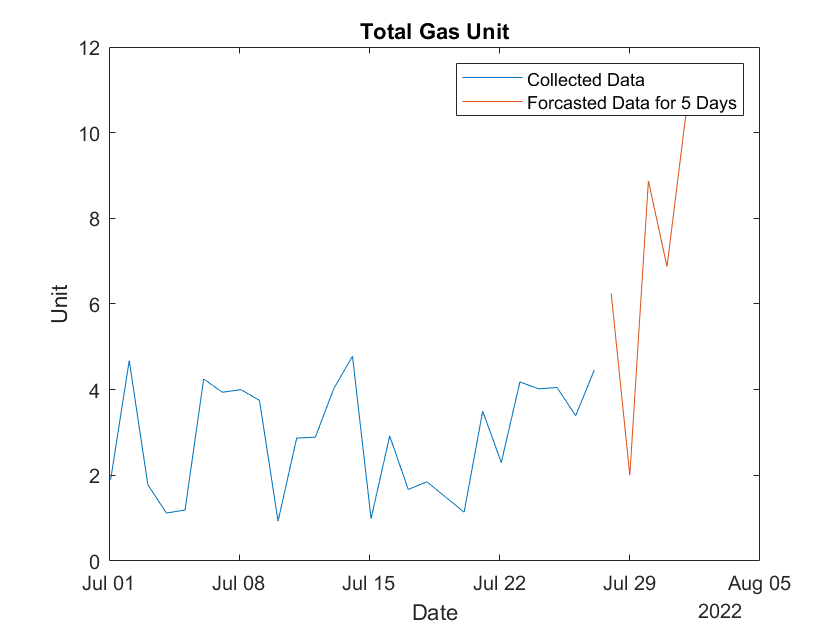

%for i=1:30

    x=datenum(time);
    t=Gas_Unit';
    X=x';
   % i
    p = polyfit(X, t, 13);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Gas Unit')
    ylabel('Unit')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end


## Total Gas Taka Prediction

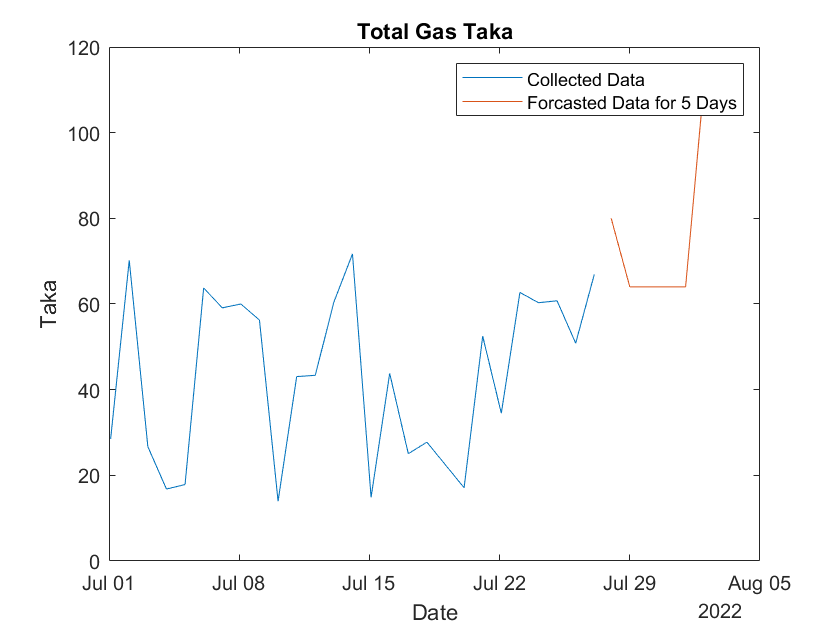

%for i=1:30

    x=datenum(time);
    t=Gas_Taka';
    X=x';
   % i
    p = polyfit(X, t, 10);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Gas Taka')
    ylabel('Taka')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end


## Total Water Taka Prediction

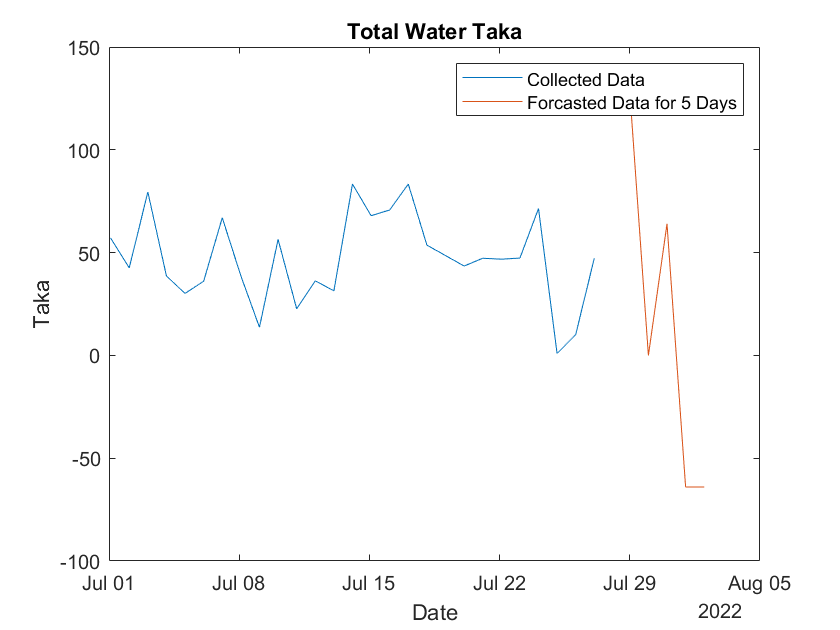

%for i=1:30

    x=datenum(time);
    t=Water_Taka';
    X=x';
   % i
    p = polyfit(X, t, 16);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Water Taka')
    ylabel('Taka')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end

## Total Water unit Prediction

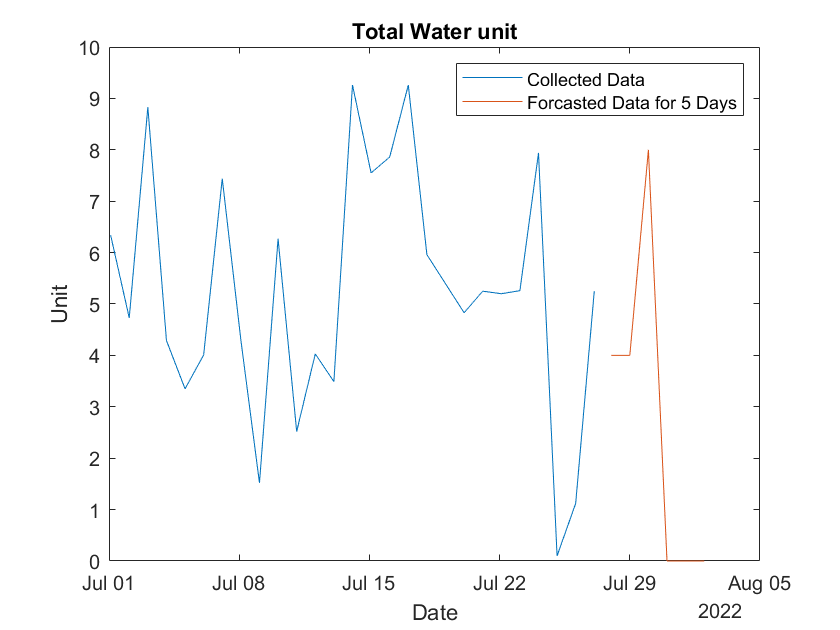

%for i=1:30

    x=datenum(time);
    t=Water_Unit';
    X=x';
    %i
    p = polyfit(X, t, 16);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Water unit')
    ylabel('Unit')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')

    
%end